# MATLAB Tutorial 7. Bode Plot

## 1. Bode Plot 그리기

clc; clear; close all
% 전달함수 만들기
s = tf('s');
G1 = tf(10);
G2 = s+2;
G3 = 1/s;
G4 = 1/(s+5);
G = G1*G2*G3*G4

G =
 
  10 s + 20
  ---------
  s^2 + 5 s
 
연속시간 전달 함수입니다.



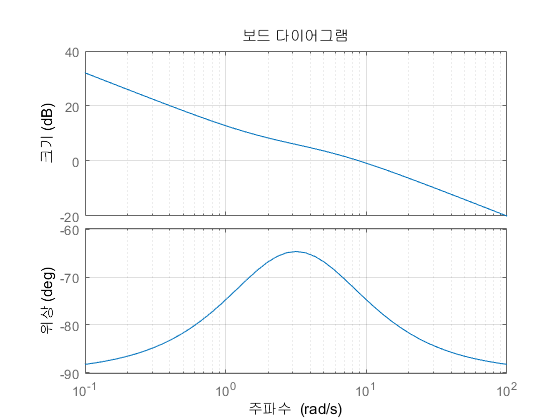

% bode plot 그리기
bode(G)
grid on

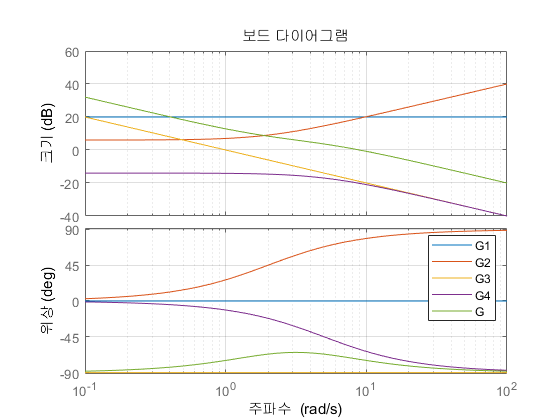

% bode plot 여러개 동시에 그리기
bode(G1, G2, G3, G4, G)
legend('G1', 'G2', 'G3', 'G4', 'G')
grid on


% bode plot 합산 관계 숫자로 확인하기
% 주파수 만들기
w = [(1:9)*0.1, (1:9)*1, (1:9)*10];

G_list = [G1, G2, G3, G4];
wlen = length(w);
gain_list = zeros(4, wlen);
phase_list = zeros(4, wlen);
for i=1:4
    % 각 기본요소의 bode plot 값 계산
    [mag, phase, wout] = bode(G_list(i), w);
    gain_list(i, :) = 20*log10(mag);
    phase_list(i, :) = phase;
end

gain_list

gain_list =    20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000
    6.0314    6.0638    6.1172    6.1909    6.2839    6.3949    6.5225    6.6652    6.8215    6.9897    9.0309   11.1394   13.0103   14.6240   16.0206   17.2428   18.3251   19.2942   20.1703   26.0638   29.5617   32.0520   33.9863   35.5678   36.9055   38.0645   39.0870
   20.0000   13.9794   10.4576    7.9588    6.0206    4.4370    3.0980    1.9382    0.9151         0   -6.0206   -9.5424  -12.0412  -13.9794  -15.5630  -16.9020  -18.0618  -19.0849  -20.0000  -26.0206  -29.5424  -32.0412  -33.9794  -35.5630  -36.9020  -38.0618  -39.0849
  -13.9811  -13.9863  -13.9950  -14.0071  -14.0226  -14.0415  -14.0637  -14.0892  -14.1179  -14.1497  -14.6240  -15.3148  -16.1278  -16.9897  -17.8533  -18.6923  -19.4939  -20

phase_list

phase_list =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.8624    5.7106    8.5308   11.3099   14.0362   16.6992   19.2900   21.8014   24.2277   26.5651   45.0000   56.3099   63.4349   68.1986   71.5651   74.0546   75.9638   77.4712   78.6901   84.2894   86.1859   87.1376   87.7094   88.0908   88.3634   88.5679   88.7270
  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000
   -1.1458   -2.2906   -3.4336   -4.5739   -5.7106   -6.8428   -7.9696   -9.0903  -10.2040  -11.3099  -21.8014  -30.9638  -38.6598  -45.0000  -50.1944  -54.4623  -57.9946  -6

% G의 bode plot 값과 기본요소들의 결과를 합산한 값과 비교
[mag_G, phase_G, wout] = bode(G, w);
mag_G = reshape(mag_G, [1, length(w)]);
gain_G = 20*log10(mag_G)

gain_G =    32.0503   26.0569   22.5798   20.1426   18.2819   16.7903   15.5568   14.5142   13.6187   12.8400    8.3863    6.2822    4.8413    3.6549    2.6043    1.6485    0.7694   -0.0437   -0.7988   -6.2407   -9.6422  -12.0977  -14.0157  -15.5883  -16.9205  -18.0760  -19.0961


gain_sum = sum(gain_list, 1)

gain_sum =    32.0503   26.0569   22.5798   20.1426   18.2819   16.7903   15.5568   14.5142   13.6187   12.8400    8.3863    6.2822    4.8413    3.6549    2.6043    1.6485    0.7694   -0.0437   -0.7988   -6.2407   -9.6422  -12.0977  -14.0157  -15.5883  -16.9205  -18.0760  -19.0961


phase_G = reshape(phase_G, [1, length(w)])

phase_G =   -88.2834  -86.5800  -84.9029  -83.2640  -81.6743  -80.1435  -78.6796  -77.2889  -75.9762  -74.7449  -66.8014  -64.6538  -65.2249  -66.8014  -68.6294  -70.4077  -72.0309  -73.4742  -74.7449  -81.6743  -84.3518  -85.7374  -86.5800  -87.1455  -87.5510  -87.8558  -88.0932


phase_sum = sum(phase_list, 1)

phase_sum =   -88.2834  -86.5800  -84.9029  -83.2640  -81.6743  -80.1435  -78.6796  -77.2889  -75.9762  -74.7449  -66.8014  -64.6538  -65.2249  -66.8014  -68.6294  -70.4077  -72.0309  -73.4742  -74.7449  -81.6743  -84.3518  -85.7374  -86.5800  -87.1455  -87.5510  -87.8558  -88.0932


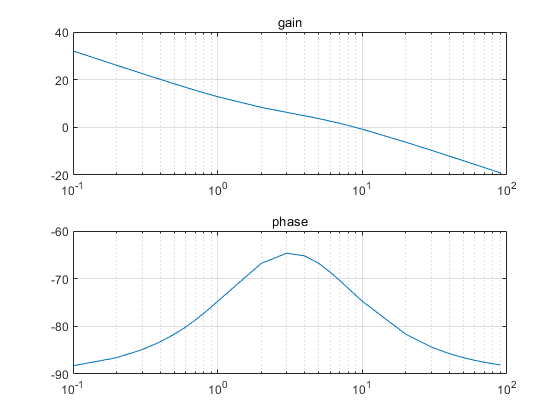

% 합산 결과를 그래프로 다시 그리기
subplot(2,1,1)
semilogx(w, gain_sum)
title('gain')
grid on
subplot(2,1,2)
semilogx(w, phase_sum)
title('phase')
grid on